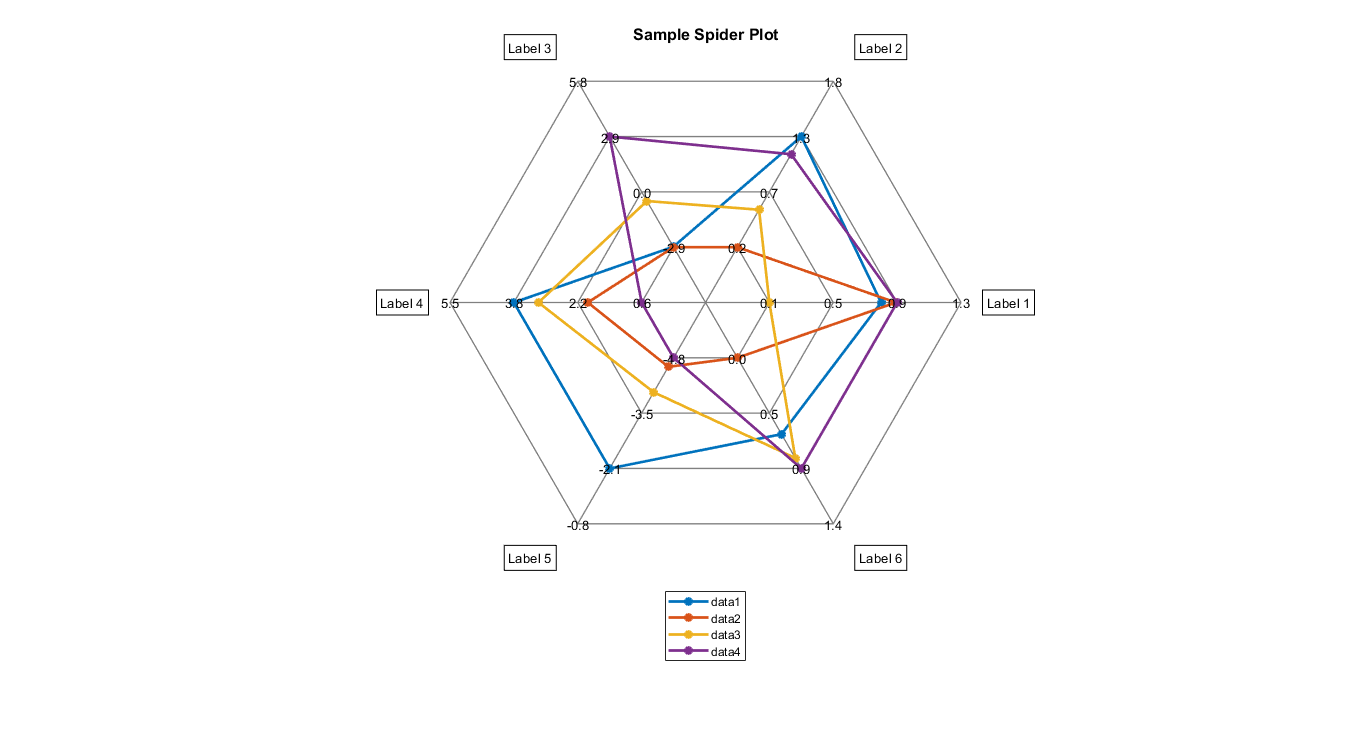

%% Example Live Script %%% 
% Clear workspace 
close all; 
clearvars; 
clc; 

% Point properties 
num_of_points = 6; 
row_of_points = 4; 

% Random data 
P = rand(row_of_points, num_of_points); 

% Scale points by a factor 
P(:, 2) = P(:, 2) * 2; 
P(:, 3) = P(:, 3) * 3; 
P(:, 4) = P(:, 4) * 4; 
P(:, 5) = P(:, 5) * 5; 

% Make random values negative 
P(1:3, 3) = P(1:3, 3) * -1; 
P(:, 5) = P(:, 5) * -1; 

% Create generic labels 
P_labels = cell(num_of_points, 1); 

for ii = 1:num_of_points 
P_labels{ii} = sprintf('Label %i', ii); 
end 

% Figure properties 
figure('units', 'normalized', 'outerposition', [0 0.05 1 0.95]); 

% Axes properties 
axes_interval = 2; 
axes_precision = 1; 

% Spider plot 
spider_plot(P, P_labels, axes_interval, axes_precision,... 
'Marker', 'o',... 
'LineStyle', '-',... 
'LineWidth', 2,... 
'MarkerSize', 5); 

% Title properties 
title('Sample Spider Plot',... 
'Fontweight', 'bold',... 
'FontSize', 12); 

% Legend properties 
legend('show', 'Location', 'southoutside');